Key topics that we'll review in this live script are:

- Angular momentum

- Principal moment of inertia

- review Eigenvalues for  general/symmetric matrix

- Rotation matrix

# Angular momentum

Similar to linear momentum (product of mass and velocity)

### 
$$\bf ^BL = {^BI} \times {^B\omega}$$


 *B-frame* about which we are determining the angular momentum is both BODY fixed AND at the body's centre of mass.

        $\pmatrix{^BL_{X} \cr ^BL_{\thinspace Y} \cr ^BL_{\thinspace  Z}} = 
\pmatrix{
^BI_{XX} & ^BI_{XY} & ^BI_{XZ} \cr
^BI_{XY} & ^BI_{YY} & ^BI_{YZ} \cr
^BI_{XZ} & ^BI_{YZ} & ^BI_{ZZ} \cr
} *
\pmatrix{^B_G\omega_X \cr 
^B_G\omega_Y \cr 
^B_G\omega_Z \cr 
}$      where      $\matrix{ 
^BI_{ZZ} = \int (X^2 + Y^2)  dm \cr
^BI_{XY} = \int(-X *Y)  dm 
}$

# Eigenvalues

The eigenvalue problem for a square matrix $A \in R^{n \times n}$:


$$A  \times \vec{v} _i = \lambda_i . \vec{v}_i 
$$
  
$$\Longrightarrow$$
  
$$det( A - \lambda_i \thinspace. \thinspace I) = 0$$


syms I_xx I_xy I_xz I_yy I_yz I_zz lambda
% define the original inertia matrix
A  = [I_xx, I_xy, I_xz;
      I_xy, I_yy, I_yz;
      I_xz, I_yz, I_zz ]  

$$A = \left(\begin{array}{ccc} I_{\mathrm{xx}} & I_{\mathrm{xy}} & I_{\mathrm{xz}}\\ I_{\mathrm{xy}} & I_{\mathrm{yy}} & I_{\mathrm{yz}}\\ I_{\mathrm{xz}} & I_{\mathrm{yz}} & I_{\mathrm{zz}} \end{array}\right)$$

Create the eigenvalue problem:  $det( A - \lambda_i \thinspace. \thinspace I) = 0$

% create the eigenvalue problem
e_mat = A - lambda*eye(3)

$$e\_mat = \left(\begin{array}{ccc} I_{\mathrm{xx}}-\lambda & I_{\mathrm{xy}} & I_{\mathrm{xz}}\\ I_{\mathrm{xy}} & I_{\mathrm{yy}}-\lambda & I_{\mathrm{yz}}\\ I_{\mathrm{xz}} & I_{\mathrm{yz}} & I_{\mathrm{zz}}-\lambda \end{array}\right)$$

det_e = det(e_mat);
det_e = collect(det_e)

$$det\_e = -\lambda^{3}+\left(I_{\mathrm{xx}}+I_{\mathrm{yy}}+I_{\mathrm{zz}}\right)\,\lambda^{2}+\left({I_{\mathrm{xy}}}^{2}+{I_{\mathrm{xz}}}^{2}+{I_{\mathrm{yz}}}^{2}-I_{\mathrm{xx}}\,I_{\mathrm{yy}}-I_{\mathrm{xx}}\,I_{\mathrm{zz}}-I_{\mathrm{yy}}\,I_{\mathrm{zz}}\right)\,\lambda -I_{\mathrm{zz}}\,{I_{\mathrm{xy}}}^{2}+2\,I_{\mathrm{xy}}\,I_{\mathrm{xz}}\,I_{\mathrm{yz}}-I_{\mathrm{yy}}\,{I_{\mathrm{xz}}}^{2}-I_{\mathrm{xx}}\,{I_{\mathrm{yz}}}^{2}+I_{\mathrm{xx}}\,I_{\mathrm{yy}}\,I_{\mathrm{zz}}$$

After determining ALL of the eignvalue ($\lambda_j$) and eigenvector ($\vec{v_j}$) pairs , we can collect them into matrices and write them as a single matrix equation:


$$A \times V =  V \times \Lambda$$
  

where

 
$$V = \pmatrix{ \vec{v}_1 \enspace, \vec{v}_1 \enspace , \vec{v}_3 \enspace , \enspace \ldots \enspace , \vec{v}_n }$$



$$\Lambda = \pmatrix{ 
\lambda_1 & 0  & 0 & 0 \ldots \cr 
0 & \lambda_2 & 0 & 0  \ldots  \cr
0 & 0 & \ddots & 0  \ldots  \cr
0 & 0 & \ldots &  \lambda_n 
}$$


**So you can see that we can convert A into a diagonal matrix using the matrix of A's eigenvectors:**


$$A \times V = V \times \Lambda  $$



$$ \Lambda = V^{-1} \times A \times V$$


Let's have a look at an example using MATLAB's `eig()` function:

*calling syntax:*

*        >>  *`[V,lambda] = eig(A)` 

* returne eigenvectors *`V`* are normalised such that the 2-norm is 1.*

% test matrix
A = [ 1, 2, 3;
      4, 0, 6;
      7, 8, 9];
% compute the eignvectors and eigenvalues  
[V, lambda] = eig(A)  

V =     0.2496    0.8346    0.0334
    0.4198   -0.0387   -0.8553
    0.8726   -0.5495    0.5170


lambda =    14.8509         0         0
         0   -1.0680         0
         0         0   -3.7829


% look at how we can diagonalise A:
A_diagonal = inv(V) * A * V

A_diagonal =    14.8509    0.0000    0.0000
   -0.0000   -1.0680    0.0000
   -0.0000    0.0000   -3.7829


## Eigenvalues When A is Symmetric 

When A is symmetric, ie: $A = A^T$, the eigenvectors corresponding to the distinct eigenvalues have a cool property - the eigenvectors are actually ORTHOGONAL, ie:

                                $\vec{v_j}^T \times \vec{v_k} = 0 $,          for $j \neq k$  and

                                
$$\vec{v_j}^T \times \vec{v_j} = {| \vec{v_j}} |^2 $$


If we normalise each of these eigenvectors so that their vector norm is 1 (ie: $\vec{v_j}^T \times \vec{v_j} = 1$), then we say that the eigenvectors are ORTHONORMAL, ie:


$$V \times V^T = I$$



$$V^T = V^{-1}$$


Therefore our diagonalization formula introduced earlier, can now be written as:


$$A \times V = V \times \Lambda  $$



$$ \Lambda = V^{-1} \times A \times V$$



$$ \Lambda = V^{T} \times A \times V$$


Let's look at an example:  

% here is a symmetric matrix A
A = [  1,   -9,  -17;
      -9,    2,   45;
     -17,   45,    3; ];
 
% compute the eignvectors and eigenvalues   
[V, lambda] = eig(A) 

V =     0.1357    0.9341   -0.3302
   -0.6848    0.3293    0.6501
    0.7160    0.1379    0.6844


lambda =   -43.2641         0         0
         0   -4.6830         0
         0         0   53.9471


% look at how we can diagonalise A:
A_should_be_diagonal = V' * A * V

A_should_be_diagonal =   -43.2641   -0.0000   -0.0000
    0.0000   -4.6830    0.0000
   -0.0000    0.0000   53.9471



% demonstrate that V is made up of orthonormal vectors
B_should_be_identity = V * V.'

B_should_be_identity =     1.0000   -0.0000   -0.0000
   -0.0000    1.0000    0.0000
   -0.0000    0.0000    1.0000


OK, so we have 3 mutually orthogonal vectors ... which is awesome, but do these 3 vectors form a Right hand rule trio of vectors?  We can ensure that they do by making the 3rd vector the cross product of the first two, eg:  $V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$

# 1- Principal Moments of Inertia

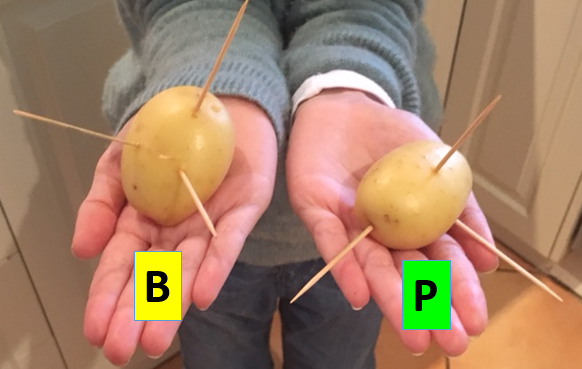

How to calculate the principal axes and principal moments of inertia, of a rigid body. 

Recall the B-frame inertia matrix $^BI$ is **symmetric**

        
$$I = 
\pmatrix{
^BI_{XX} & ^BI_{XY} & ^BI_{XZ} \cr
^BI_{XY} & ^BI_{YY} & ^BI_{YZ} \cr
^BI_{XZ} & ^BI_{YZ} & ^BI_{ZZ} \cr
}$$
   

Let's find another co-ordinate frame P such that the inertia matrix about this new *P-frame* is diagonal.  We call this *P-frame* the **PRINCIPAL** frame and the corresponding diagonal inertia matrix the **PRINCIPAL **moment of inertia matrix $^PI$, ie:


$$^PL = {^PI} \times {^P\omega} \qquad where \qquad {^PI} = \pmatrix{
I_1 & 0 & 0 \cr
0 & I_2 & 0 \cr
0 & 0 & I_3 \cr
} $$


To determine this new **PRINCIPAL** frame we need to find a co-ordinate transformation $^PR_B$ that converts co-ordinates in the original body *"B-frame"* into their corresponding co-ordinates in the new **PRINCIPAL** *"P-frame".  *ie: we have a FIXED *B-frame*, and we will rotate a *P-frame* relative to B. And $^PR_B$ is just the PASSIVE rotation matrix which relates components in one frame to another.  We'll define this relationship as  ${^Pu} = {^PR_B} \times {^Bu}$.  Consider then the following:


$${^P\omega} = {^PR_B} \times {^B\omega} \qquad \Longrightarrow \qquad {^B\omega} = {^PR_B^T} \times {^P\omega}$$



$${^PL} = {^PR_B} \times {^BL} \qquad \Longrightarrow \qquad {^BL} = {^PR_B^T} \times {^PL}$$


Now let's focus on the angular momentum described in the B-frame


$$^BL = {^BI} \times {^B\omega}$$



$$({^PR_B^T} \times {^PL}) = {^BI} \times  ({^PR_B^T} \times {^P\omega})$$



$$^PL = ({^PR_B \times {^BI} \times {^PR_B^T}) \times {^P\omega}$$



$$^PL = {^PI} \times {^P\omega}   \qquad where \qquad {^PI} = ({^PR_B \times {^BI} \times {^PR_B^T}) $$
   

The equation for $^PI$ has the form ($\bf ^PI = H\times {^BI} \times H^T$) which is similar in shape to what we saw when we discussed eigenvectors of symmetric matrices.  As observed earlier, we know that $^BI$ is **symmetric** , and as such we can use the eigenvectors of $^BI$ to construct a diagnonal matrix from $^BI$ ... and that's exactly what we want to do. 


$${^BI}  \times \vec{v} _i = \lambda_i . \vec{v}_i $$



$${^BI} \times V =  V \times \Lambda \qquad \Longrightarrow \qquad \Lambda = 
{^PI} = 
V^{-1} \times {^BI} \times V $$


So the 2 equations that pull everything together are:


$$\matrix{
 {^PI} = & ({^PR_B \times {^BI} \times {^PR_B^T})  & \cr
{^PI} = & V^{-1} \times {^BI} \times V & 
= & V^T \times {^BI} \times V

}$$


So ? - So we've finally converged on some useful results:

- The **PRINCIPAL** moments of inertia are the eigenvalues $\lambda$ of ${^BI}$.

- The orientation of the **PRINCIPAL** *P-frame* relative to the initial *B-frame*, is given by the passive rotation matrix $^PR_B = {V^{-1}} = V^T$ , where:  ${^Pu} = {^PR_B} \times {^Bu}$.

***RECALL the one small detail: *** *One small detail that we need to mention is that in order to interpret *$[V]$* as a rotation matrix, we need to ensure that the 3 basis vectors in *$[V]$* form a right handed co-ordinate frame, ie: just because 3 unit vectors are mutually orthogonal doesn't mean they form a RH frame. So an easy way to do this is to redefine *$[V]$* as:*


$$V = [\vec{v_1}, \quad \vec{v_2}, \quad (\vec{v_1} \times \vec{v_2})]$$


## Let's look at an example:

In the previous section we established that the PRINCIPAL moments of inertia could be found by solving an eigenvalue problem.  The Principal moments of Inertia $^PI$ are the eigenvalues of the original inertia matrix $^BI$.   SO let's solve this eigenvalue problem.  In this example we're going to :

format longG
bIn = [  
        117.81      -59.685       56.046
       -59.685       171.95       14.243
        56.046       14.243       186.33
      ];      

## ***Find the ***$^PI$***:***

Now calculate the Principal inertia values using the `eig()` function

% find igenvalues & eigenvectors
[V, Ip_mat] = eig(bIn)

Check that we have a RH co-ordinate frame.  We know that $\vec{i} \times \vec{j} = \vec{k}$

tmp_3 = cross( V(:,1), V(:,2) );
% CHECK RH co-ordinate frame 
tmp_diff = tmp_3 - V(:,3);
tmp_mag  = norm(tmp_diff);
if( tmp_mag < 1e-7 )
    fprintf('\n ... yep V gives us a RH rule frame !');
else
    warning('Modifying V, so it is a RH frame');
    V(:,3) = tmp_3;

V =         -0.797353030582144        -0.111887356741905        -0.593050894968366
        -0.458290582862403         0.751631273019369          0.47436291073283
         0.392680386932056         0.650024344790711         -0.65059239535849


Ip_mat =           55.9036216319413                         0                         0
                         0          193.152275905814                         0
                         0                         0          227.034102462245


end

Demonstrate V is orthonormal:

% demonstrate that V is made up of orthonormal vectors
figure;  
imagesc(V * V.'); 
colorbar

**Summarise what we have so far**

So we finally have our PRINCIPAL moments of inertia $({^PI})$ AND we know how the PRINCIPAL axes are orientated relative to the B-frame $({V^{-1}} \equiv {^PR_B} )$ .. AND we've checked for a RH frame:

% so let's summarise what we've got
Ip_mat
V


 ... yep V gives us a RH rule frame !

# passive rotations and the DCM

Recall some of the formulaes mentioned earlier:

- 
$${^Pu} = {^PR_B} \times {^Bu}$$


- 
$$ {^PR_B}  = {V^{-1}} = V^T$$


pRb = V.'

First let's plot the unit vectors of our original B-frame:

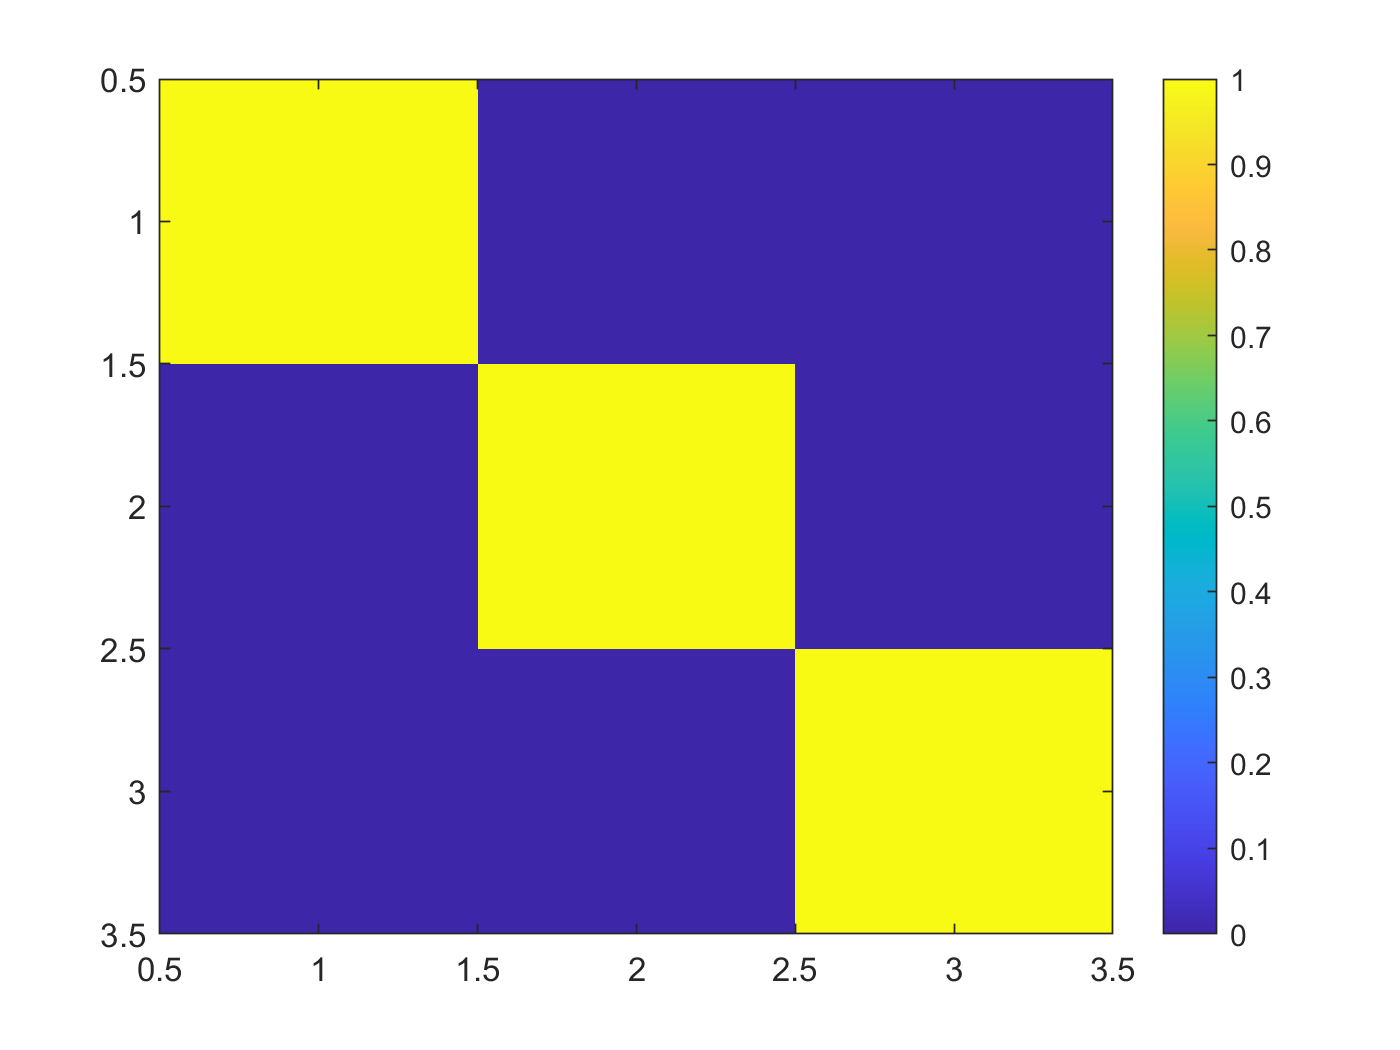

figure
   % Plot the B-frame UNIT vectors 

   bx_u = [1;0;0];
   by_u = [0;1;0];
   bz_u = [0;0;1];
       

Ip_mat =           55.9036216319413                         0                         0
                         0          193.152275905814                         0
                         0                         0          227.034102462245


   if(isempty(gca))

V =         -0.797353030582144        -0.111887356741905        -0.593050894968366
        -0.458290582862403         0.751631273019369          0.47436291073283
         0.392680386932056         0.650024344790711         -0.65059239535849


       gca = axes;
   end
   hold('on');
   plot3([0;bx_u(1)], [0;bx_u(2)], [0;bx_u(3)], '-r', 'LineWidth', 5);  
   plot3([0;by_u(1)], [0;by_u(2)], [0;by_u(3)], '-b', 'LineWidth', 5);  

pRb =         -0.797353030582144        -0.458290582862403         0.392680386932056
        -0.111887356741905         0.751631273019369         0.650024344790711
        -0.593050894968366          0.47436291073283         -0.65059239535849


   plot3([0;bz_u(1)], [0;bz_u(2)], [0;bz_u(3)], '-g', 'LineWidth', 5);
   
   axis('equal'); grid('on'); xlabel('Xb'); ylabel('Yb'); zlabel('Zb');
       xlim([-1.5, 1.5]);  ylim([-1.5, 1.5]);  zlim([-1.5, 1.5]);
   view(3);
      title('The B-frame UNIT vectors')

Let's plot the P-frame unit vectors, but draw them in the B-frame.  To compute the components of the P-frame expressed in terms of the B-frame we can just use our passive rotation matrices.  Recall what our passive rotation $({^PR_B})$matrix does:  


$${^Pu} = {^PR_B} \times {^Bu} $$


So to transform our P-frame unit vectors into their corresponding components in the B-frame we use the following PASSIVE rotation matrix:


$${^Bu} = {(^PR_B)^T} \times {^Pu}$$


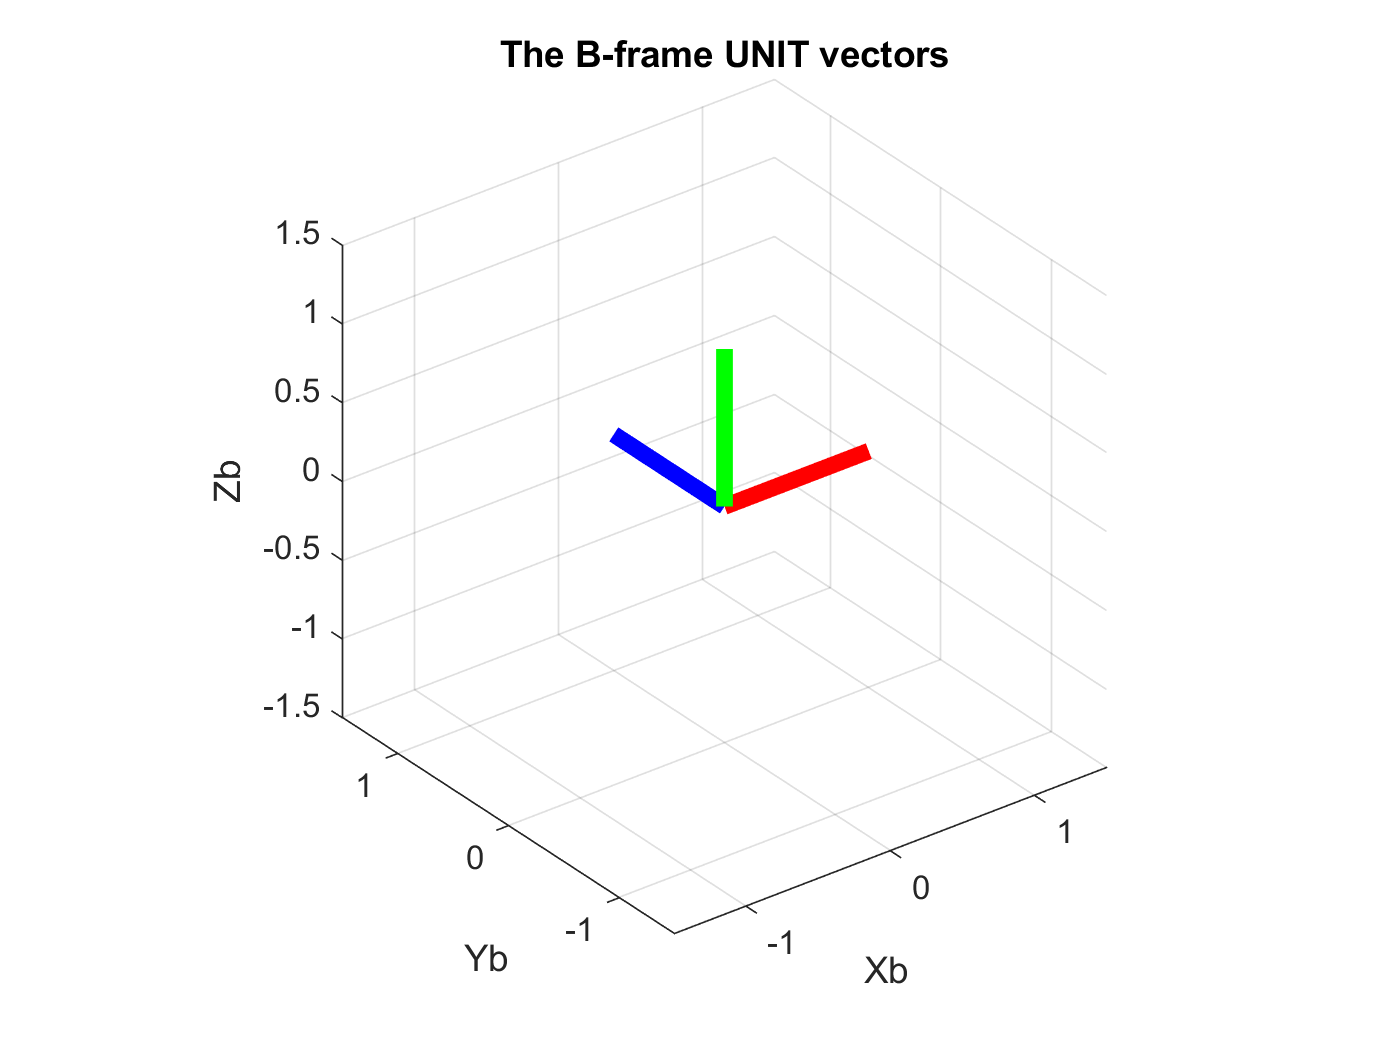

figure
   % express the unit vectors of P into their components in the B-frame 
   b_xi_p = pRb.' * [1;0;0];
   b_yi_p = pRb.' * [0;1;0];
   b_zi_p = pRb.' * [0;0;1];

   if(isempty(gca))
       gca = axes;
   end
   hold('on');
   plot3([0;b_xi_p(1)], [0;b_xi_p(2)], [0;b_xi_p(3)], '-r', 'LineWidth', 5);  
   plot3([0;b_yi_p(1)], [0;b_yi_p(2)], [0;b_yi_p(3)], '-b', 'LineWidth', 5);  

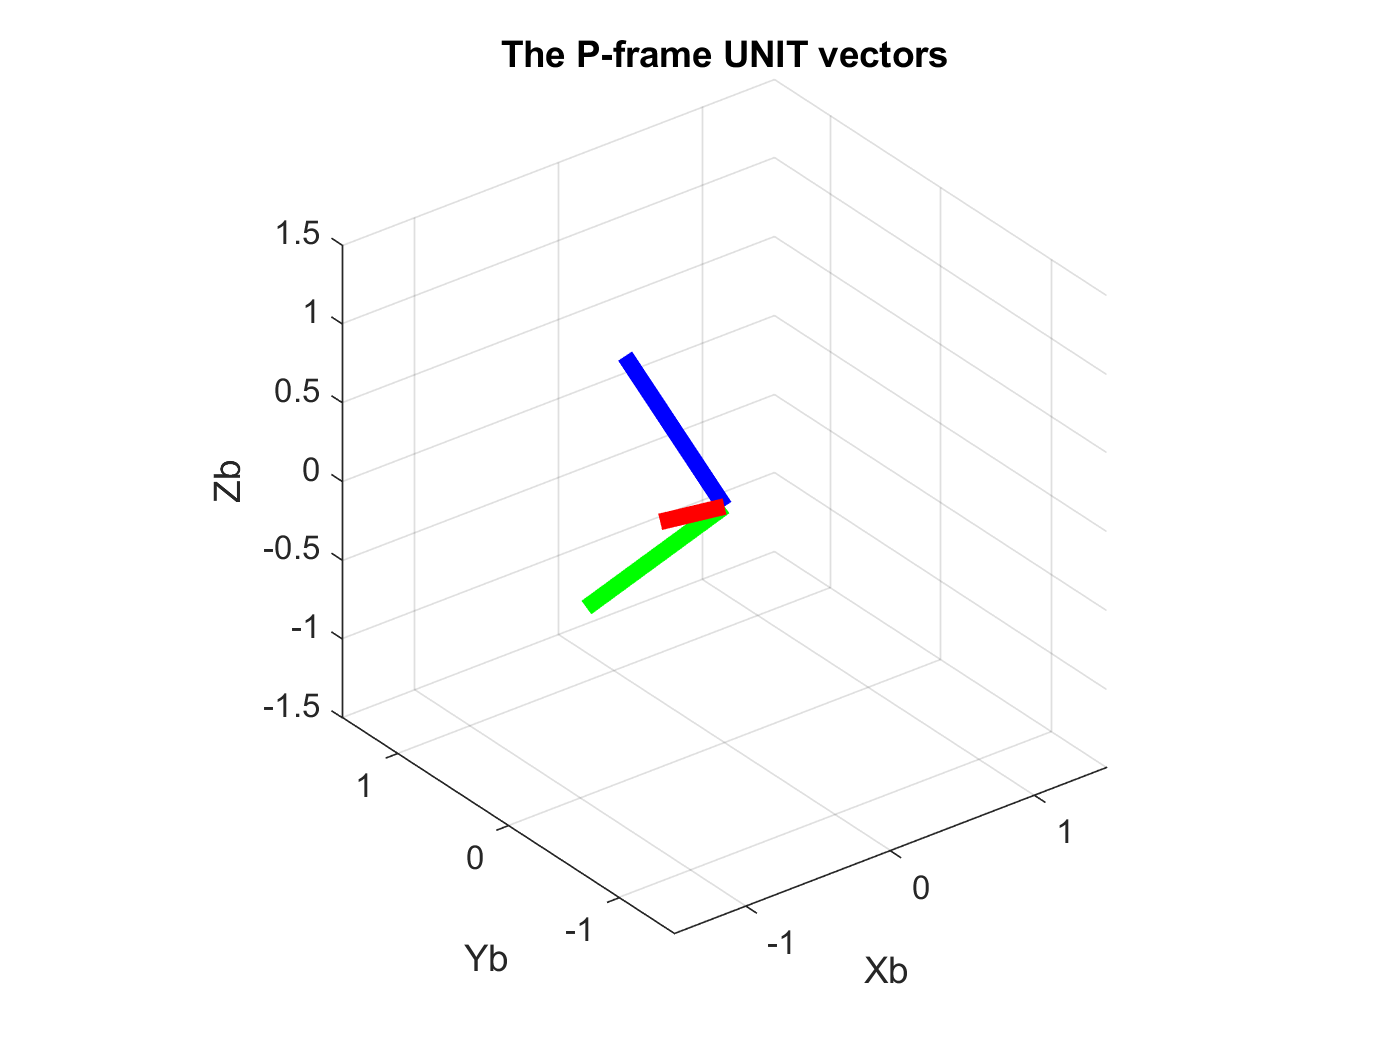

   plot3([0;b_zi_p(1)], [0;b_zi_p(2)], [0;b_zi_p(3)], '-g', 'LineWidth', 5);
   
   axis('equal'); grid('on'); xlabel('Xb'); ylabel('Yb'); zlabel('Zb');
       xlim([-1.5, 1.5]);  ylim([-1.5, 1.5]);  zlim([-1.5, 1.5]);
   view(3);
   title('The P-frame UNIT vectors')

# References

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`